x = 0:0.001:2;
%Create EEG signal from various sinusoids
%Amplitudes reflect signal contribution
EEG = 1*sin(2*2*pi*x); %2Hz Delta
EEG = EEG + 1*sin(6*2*pi*x); %6Hz Theta
EEG = EEG + 1*sin(10*2*pi*x); %10Hz Alpha
EEG = EEG + 4*sin(20*2*pi*x); %20Hz Beta
EEG = EEG + 2*sin(50*2*pi*x); %50Hz Gamma

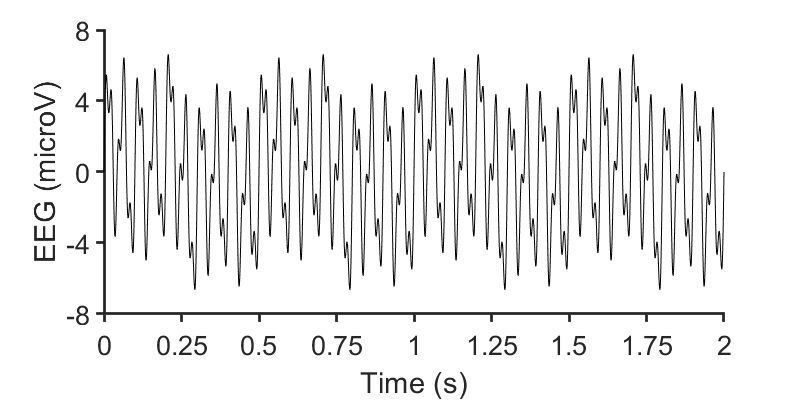

h = plot(x,EEG,'k');
xlabel('Time (s)','FontSize',20)
ylabel('EEG (microV)','FontSize',20,'Rotation',90)
axis([0 2 -8 8])
set(gca,'Box','off')
set(gca,'TickDir','Out')
set(gca,'XTick',[0:0.25:2])
set(gca,'YTick',[-8:4:8])
set(gca,'FontSize',20)
set(gca,'LineWidth',2)
set(gcf,'Color','white')
set(gcf,'Position',[400 400 800 400])
set(gcf,'PaperPosition',[4 4 8 4])
print('-depsc','FrequencyAnalysis.eps','-r600');